robot = importrobot('urdf/Si/Si_PSM.urdf')

robot =   rigidBodyTree with properties:

     NumBodies: 17
        Bodies: {1×17 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×17 cell}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


showdetails(robot)

--------------------
Robot: (17 bodies)

 Idx                             Body Name         Joint Name         Joint Type                             Parent Name(Idx)   Children Name(s)
 ---                             ---------         ----------         ----------                             ----------------   ----------------
   1                    PSM1_psm_base_link              fixed              fixed                                     world(0)   PSM1_outer_yaw_link(2)  
   2                   PSM1_outer_yaw_link                yaw           revolute                        PSM1_psm_base_link(1)   PSM1_outer_pitch_link(3)  PSM1_outer_pitch_back_link(13)  PSM1_outer_pitch_front_link(17)  
   3                 PSM1_outer_pitch_link              pitch           revolute                       PSM1_outer_yaw_link(2)   PSM1_tool_main_link(4)  
   4                   PSM1_tool_main_link          insertion          prismatic                     PSM1_outer_pitch_link(3)   PSM1_tool_wrist

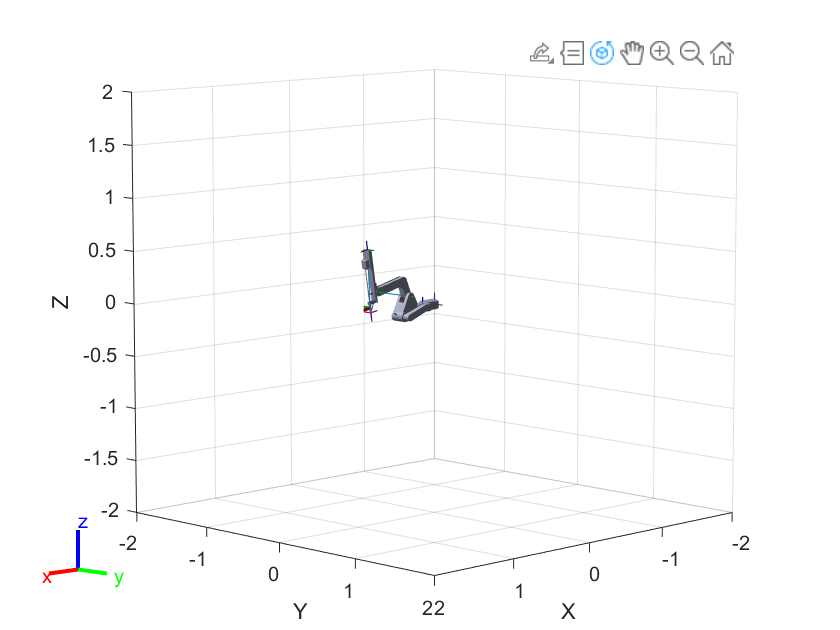

ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



show(robot)

gen3 = loadrobot("kinovaGen3")

gen3 =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Shoulder_Link'  'HalfArm1_Link'  'HalfArm2_Link'  'ForeArm_Link'  'Wrist1_Link'  'Wrist2_Link'  'Bracelet_Link'  'EndEffector_Link'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


showdetails(gen3)

--------------------
Robot: (8 bodies)

 Idx               Body Name         Joint Name         Joint Type               Parent Name(Idx)   Children Name(s)
 ---               ---------         ----------         ----------               ----------------   ----------------
   1           Shoulder_Link          Actuator1           revolute                   base_link(0)   HalfArm1_Link(2)  
   2           HalfArm1_Link          Actuator2           revolute               Shoulder_Link(1)   HalfArm2_Link(3)  
   3           HalfArm2_Link          Actuator3           revolute               HalfArm1_Link(2)   ForeArm_Link(4)  
   4            ForeArm_Link          Actuator4           revolute               HalfArm2_Link(3)   Wrist1_Link(5)  
   5             Wrist1_Link          Actuator5           revolute                ForeArm_Link(4)   Wrist2_Link(6)  
   6             Wrist2_Link          Actuator6           revolute                 Wrist1_Link(5)   Bracelet_Link(7)  
   7           Br

robot.DataFormat = 'column';
q_0 = [40 0 0 0 0 0 0 0 0 0 0]'*pi/180;
q_home = [0 40 -40 40 0 0 0 0 0 0 0]'*pi/180;
q_home(5) = 0.12;
q_0(5) = 0.12;
eeName = 'PSM1_tool_wrist_sca_ee_link';
T_home = getTransform(robot, q_home, eeName);
q_home1 = -q_home;
q_home1(5) = 0.12;
q_1 = -q_0;
q_1(5) = 0.12;

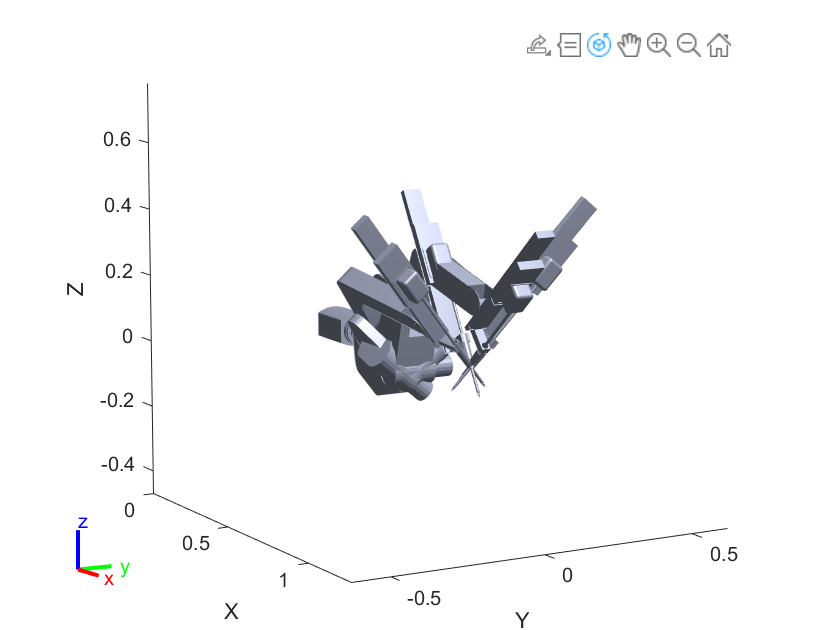

show(robot,q_home,Frames="off");
axis auto;
view([60,10]);
hold on
show(robot,q_0,Frames="off");
show(robot,q_home1,Frames="off");
show(robot,q_1,Frames="off");
grid off

robot = importrobot('urdf/Classic/Cls_PSM.urdf')

robot =   rigidBodyTree with properties:

     NumBodies: 17
        Bodies: {1×17 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×17 cell}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


showdetails(robot)

--------------------
Robot: (17 bodies)

 Idx                             Body Name         Joint Name         Joint Type                             Parent Name(Idx)   Children Name(s)
 ---                             ---------         ----------         ----------                             ----------------   ----------------
   1                    PSM1_psm_base_link              fixed              fixed                                     world(0)   PSM1_outer_yaw_link(2)  
   2                   PSM1_outer_yaw_link                yaw           revolute                        PSM1_psm_base_link(1)   PSM1_outer_pitch_link(3)  PSM1_outer_pitch_back_link(13)  PSM1_outer_pitch_front_link(17)  
   3                 PSM1_outer_pitch_link              pitch           revolute                       PSM1_outer_yaw_link(2)   PSM1_tool_main_link(4)  
   4                   PSM1_tool_main_link          insertion          prismatic                     PSM1_outer_pitch_link(3)   PSM1_tool_wrist

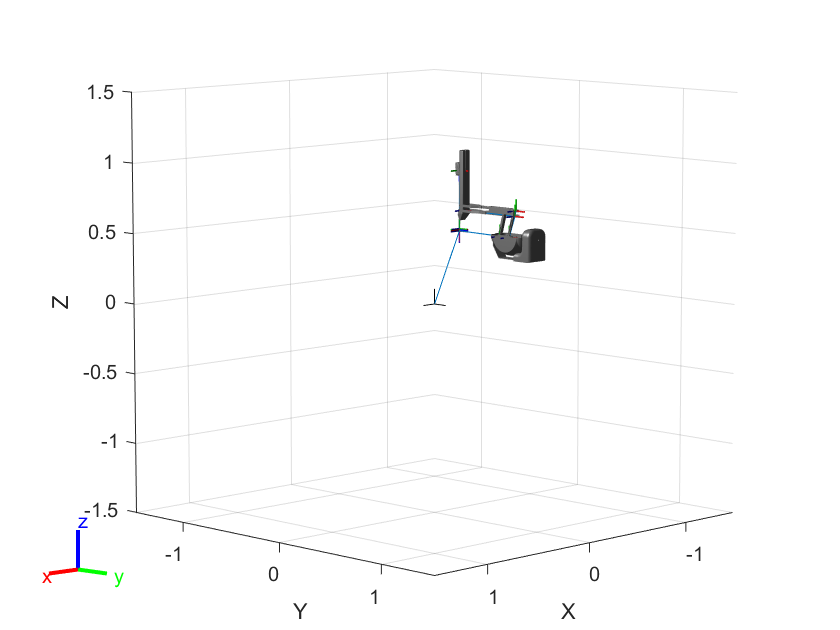

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot)

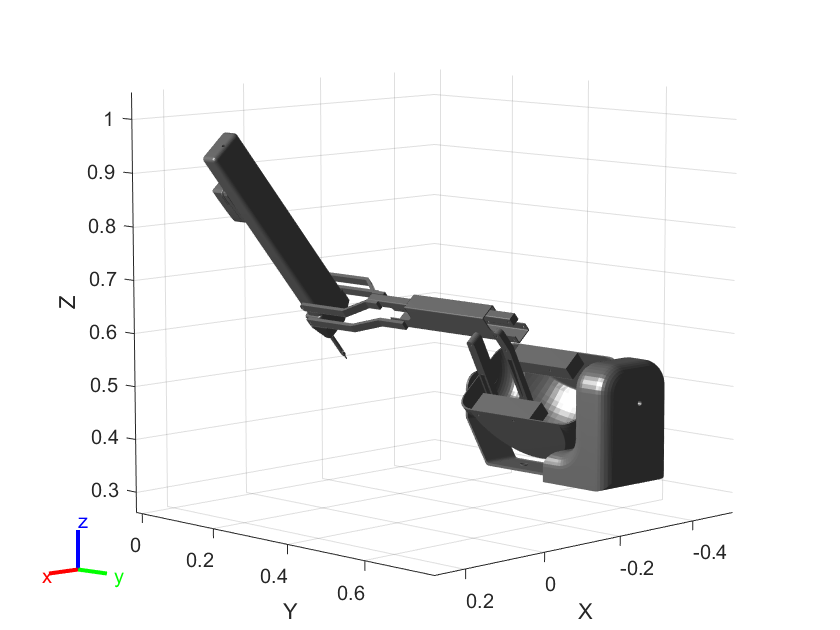

robot.DataFormat = 'column';
% q_0 = [40 0 0 0 0 0 0 0 0 0 0]'*pi/180;
q_home = [40 0 0 0 0 0 0 0 0 0 0 0 0 0]'*pi/180;
% q_home(3) = 0.12;
% q_0(5) = 0.12;
eeName = 'PSM1_tool_tip_link';
T_home = getTransform(robot, q_home, eeName);
% q_home1 = -q_home;
% q_home1(5) = 0.12;
% q_1 = -q_0;
% q_1(5) = 0.12;
show(robot,q_home,Frames="off");
axis auto;

% view([60,10]);

geoJacob = geometricJacobian(robot,q_home,"PSM1_tool_tip_link")

geoJacob =    -0.0000    0.7660         0   -0.6428    0.7660   -0.0000         0         0         0         0         0         0         0         0
    1.0000    0.0000         0   -0.0000    0.0000    1.0000         0         0         0         0         0         0         0         0
   -0.0000   -0.6428         0   -0.7660   -0.6428   -0.0000         0         0         0         0         0         0         0         0
   -0.0028   -0.0000   -0.6428   -0.0000   -0.0000   -0.0078         0         0         0         0         0         0         0         0
   -0.0000    0.0037   -0.0000   -0.0000    0.0193   -0.0000         0         0         0         0         0         0         0         0
    0.0024   -0.0000   -0.7660    0.0000   -0.0000    0.0066         0         0         0         0         0         0         0         0
